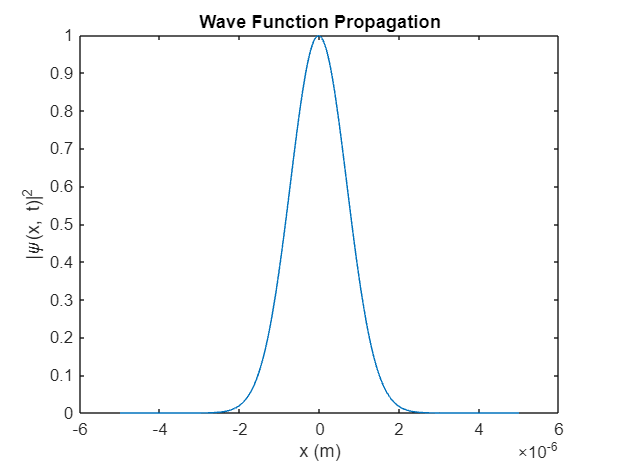

% I

hbar = 1.0545718e-34; 
m = 1.674927471e-27; 
t0 = 0; 
t = 1e-6; 
L = 1e-5; 
N = 1024; 
dx = L / N; 
x = linspace(-L/2, L/2, N); 
dk = 2 * pi / L; 
k = dk * (-N/2:N/2-1);


x0 = 0; 
p0 = 1e-24;
a = 1e-6;
psi0 = exp(-(x - x0).^2 / (2 * a^2)) .* exp(1i * p0 * x / hbar);


psi_k0 = fftshift(fft(psi0));


U_k = exp(-1i * (hbar^2 * k.^2 / (2 * m)) * (t - t0) / hbar);
psi_k_t = psi_k0 .* U_k;


psi_t = ifft(ifftshift(psi_k_t));


figure;
plot(x, abs(psi_t).^2);
xlabel('x (m)');
ylabel('|\psi(x, t)|^2');
title('Wave Function Propagation');